## Overview:

In aprevious step we generated a collection of potential control laws for stabilizing the quadcopter-pendulum vehicle.  What we'll do next is use these candidate control laws with our NON-linear vehicle dynamics model.  Specifically we'll automate the execution of our Simulink model.

Setup some CONFIG parameters for running this script

tf_run_sweep_of_ALL_candidate_laws  = true;  % will take approximately 30 minutes
tf_run_sweep_of_GOOD_candidate_laws = true;

The name of the Nonlinear vehicle Simulink model

THE_MODEL = 'bh_SM_quad_and_PEND';
%THE_MODEL = "bh_compare_hand_to_SM_quad_pend";

## PHASE_01:    Do a sweep of ALL candidate Control laws:

Load the list of candidate control laws

candidates_T = load('bh_candidate_K_laws.mat',"WORK_list")

Specify some Simulation parameters 

sim_opts_T = LOC_sim_opts();

set_param(0, 'CallbackTracing', 'off')

Now sweep through the candidate control laws: 

if( true == tf_run_sweep_of_ALL_candidate_laws )

   fprintf('\n ... your WORK_list has <%d> designs in it', length(candidates_T.WORK_list) );

    good_run_inds = LOC_run_ALL_candidates(THE_MODEL, sim_opts_T, candidates_T)
    
    % Save the list of GOOD candidates
    good_candidates_T           = [];
    good_candidates_T.WORK_list = candidates_T.WORK_list(good_run_inds);
    WORK_list                   = candidates_T.WORK_list(good_run_inds);
    
    save('bh_good_candidate_K_laws.mat',"good_candidates_T", "WORK_list");    
end

## PHASE_02:    Do a sweep of the GOOD candidate Control laws

if(true == tf_run_sweep_of_GOOD_candidate_laws)
    load('bh_good_candidate_K_laws.mat',"good_candidates_T")
    
    fprintf('\n ... your WORK_list has <%d> designs in it', length(good_candidates_T.WORK_list) );
    
    try
       LOC_run_GOOD_candidates(THE_MODEL, sim_opts_T, good_candidates_T)
    catch
        fprintf("\n .... sim ended prematurely ! ");
    end
end

## PHASE_03:    Manually inspect GOOD candidate Control laws

Attention:  the Length of your WORK_list is:

length(good_candidates_T.WORK_list)

ans = 9

Now explore one of the candidate designs:

ind = 3;
if(ind > length(good_candidates_T.WORK_list))
    error('###_WARNING - your WORK_list array is not that long !')
    %ind = length(good_candidates_T.WORK_list);
end

cand_T           = [];
cand_T.WORK_list = good_candidates_T.WORK_list(ind);

% open_system(THE_MODEL)
sim_opts_T.EnablePacing = 'on';
set_param(0, 'CallbackTracing', 'off');
LOC_run_GOOD_candidates(THE_MODEL, sim_opts_T, cand_T)


 ... Starting a BATCH run of   1 Simulations

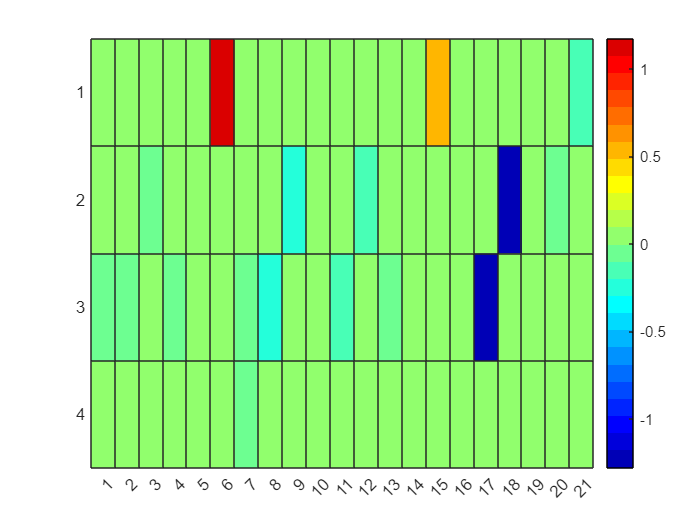


figure;  heatmap( good_candidates_T.WORK_list(ind).K,'Colormap',jet(25));

## And we're done

set_param(0, 'CallbackTracing', 'on')

# **Local Subfunctions only beyond this point**

**Specify an options struct for the**` sim()`** function**

function sim_opts_T = LOC_sim_opts()
    sim_opts_T.SrcWorkspace   = 'current';
    sim_opts_T.StartTime      = '0';
    sim_opts_T.StopTime       = '5';
    sim_opts_T.SimMechanicsOpenEditorOnUpdate = 'off';
    sim_opts_T.ReturnWorkspaceOutputs = 'on';
    sim_opts_T.SaveTime = 'on';
    sim_opts_T.TimeSaveName = 'tout';
    
end

**Run the Simulink model programatically.**

function t = LOC_run_a_sim(MODEL_NAME, my_opts_struct, my_K)

    %  load parameters that model needs
    bh_create_local_params_QP

    VEH_AND_PEND_BUS = evalin('base', 'VEH_AND_PEND_BUS');
    PEND_BUS         = evalin('base', 'PEND_BUS');
    
    % define the control law
    K = my_K;
    
    % run the sim
    simOut = sim( MODEL_NAME, my_opts_struct);

    % extract the signal of interest
    t     = simOut.tout;
end

**PHASE_01 - run ALL candidate control laws**

function good_run_inds = LOC_run_ALL_candidates(THE_MODEL, sim_opts_T, candidates_T)
    
    good_run_inds = [];
    for COUNT=1:length(candidates_T.WORK_list)
        
        THE_K = candidates_T.WORK_list(COUNT).K;
        
        try
           t         = LOC_run_a_sim(THE_MODEL, sim_opts_T, THE_K);
           good_run_inds = [good_run_inds, COUNT];
        catch
        end
        
        if(0==mod(COUNT,10)) 
            fprintf('\n ... finished %3d of %4d', COUNT, length(candidates_T.WORK_list));
        end
    end

end

**PHASE_02 - run only the GOOD control laws**

function  LOC_run_GOOD_candidates(THE_MODEL, sim_opts_T, good_candidates_T)
    
    sim_opts_T.SimMechanicsOpenEditorOnUpdate = 'on';
    sim_opts_T.StopTime                       = '50';
    
    fprintf("\n ... Starting a BATCH run of %3d Simulations", length(good_candidates_T.WORK_list) );

    for COUNT=1:length(good_candidates_T.WORK_list)
        
        THE_K     = good_candidates_T.WORK_list(COUNT).K;    
        t         = LOC_run_a_sim(THE_MODEL, sim_opts_T, THE_K);
        
        if(0==mod(COUNT,10)) 
            fprintf('\n ... finished %3d of %4d', COUNT, length(good_candidates_T.WORK_list));
        end
    end
end